# Tema 2.2 - Derivación Numérica

## Ejemplo 1 

Calcular la derivada en todos los puntos por forward difference y por backward difference.

x=[0:0.2:0.4];y=[0 0.7414 1.3718];
disp([x',y'])

         0         0
    0.2000    0.7414
    0.4000    1.3718



## Ejemplo 2

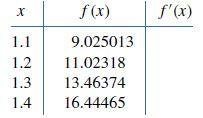

Calcular la derivada en todos los puntos con una fórmula de orden el más alto posible orden, O(h) i O(h^2)

x=linspace(1.1,1.4,4); y=[9.025013,11.02318,13.46374,16.44465];
disp([x',y'])

ERRORES. Los datos se corresponden a la función $y=e^{2x}$ la derivada es $y'=2e^{2x}$. Crear tabla para visualitzar error absoluto en las fórmulas usadas

## Ejemplo 3

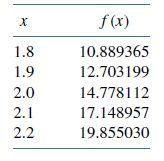

Calcular f'(2.0) con h=0.1 y h=02. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

x=linspace(1.8,2.2,5); y=x.*exp(x); disp([x',y'])

#### Ejercicio 1 - CNGuia-Lab9

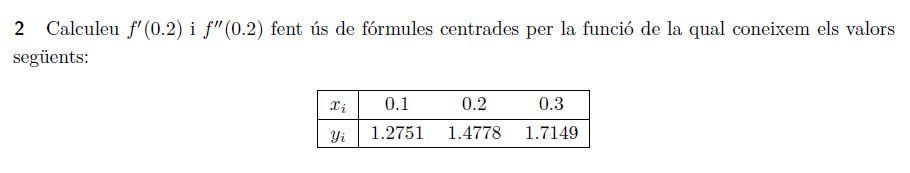

#### Ejercicio 2 - CNGuia-Lab9

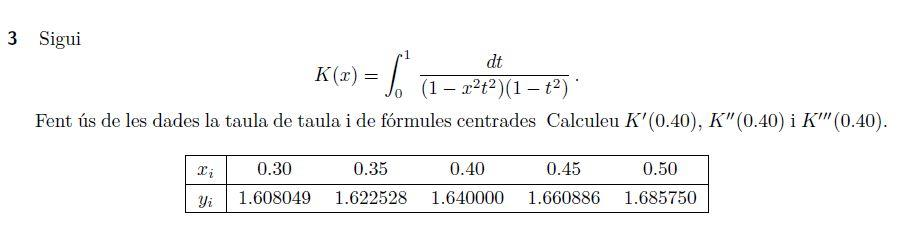

# Error en las fórmulas de diferenciación numérica 

#### PRÀCTICA 22 - CNGuia-Lab9

format short g
f=@(x)log(x);
k = 0:14;
h = 1./10.^k;
fp = ones(length(h),1);
for n=1:length(k)
    fp(n) = (f(2+h(n))-f(2))/h(n);
end
er = abs(fp-0.5);
resultats = [k'  fp  er]

resultats =             0      0.40547     0.094535
            1       0.4879     0.012098
            2      0.49875    0.0012458
            3      0.49988   0.00012496
            4      0.49999     1.25e-05
            5          0.5     1.25e-06
            6          0.5   1.2494e-07
            7          0.5   1.3031e-08
            8          0.5   3.0387e-09
            9          0.5    4.137e-08


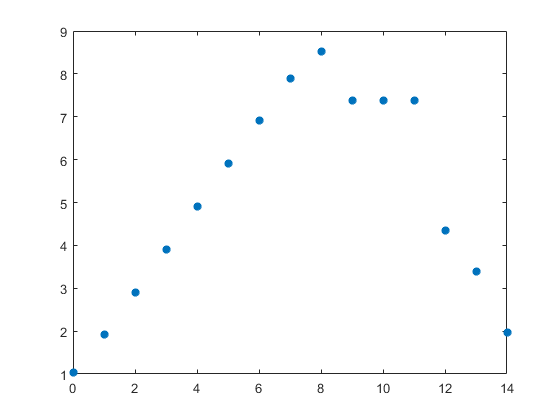

dc = -log10(er);
plot(k,dc,'*', 'LineWidth',2)

# Approximate Derivatives with diff

Consultar la ayuda de Matlab para la instrucción diff y trasladar ejemplo función seno. 

# Derivación simbólica con Matlab 

Ejemplos extraídos del help

#### **Differentiate Function**

Find the derivative of the function `sin(x^2)`.

syms f(x)


Find the value of the derivative at `x = 2`. Convert the value to double.

**Differentiation with Respect to Particular Variable**

Find the first derivative of this expression: $sin(xt^2)$

syms x t


**Mixed Derivatives**

Differentiate this expression with respect to the variables `x` and `y`:

syms x y
diff(x*sin(x*y), x, y)

#### Document preparat per Mª Àngela Grau Gotés (prof. responsable MN)